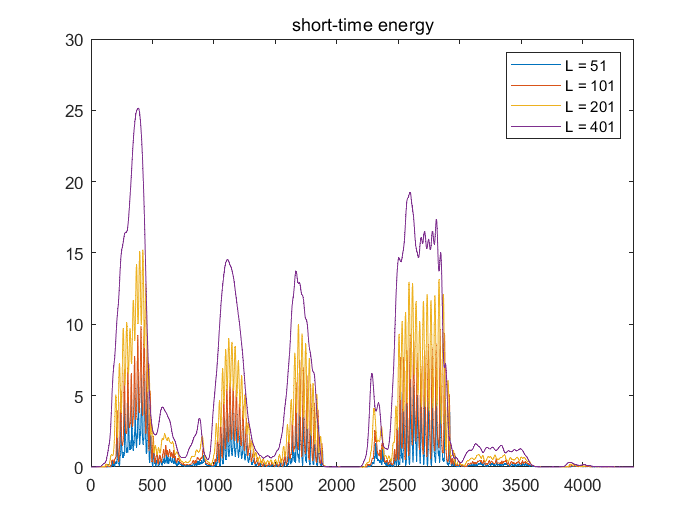

[signal, Fs] = audioread('test_16k.wav');
R = 5; % window_shift;
L = [51, 101, 201, 401]; %duration;
figure;

% short-time energy
figure()
for j = 1:4
    stenergy = zeros(1, round((length(signal)-L(j))/R));
    window = hamming(L(j));
    window_e = window.^2;
    for i = 1:length(stenergy)
        map_i = (i-1)*R+1;
        stenergy(i) = sum((signal(map_i:(map_i+L(j)-1)).^2).*window_e);
    end
    plot(stenergy);title(sprintf('short-time energy'));xlim([0,length(stenergy)]);
    hold on
end
legend('L = 51','L = 101','L = 201','L = 401')
hold off

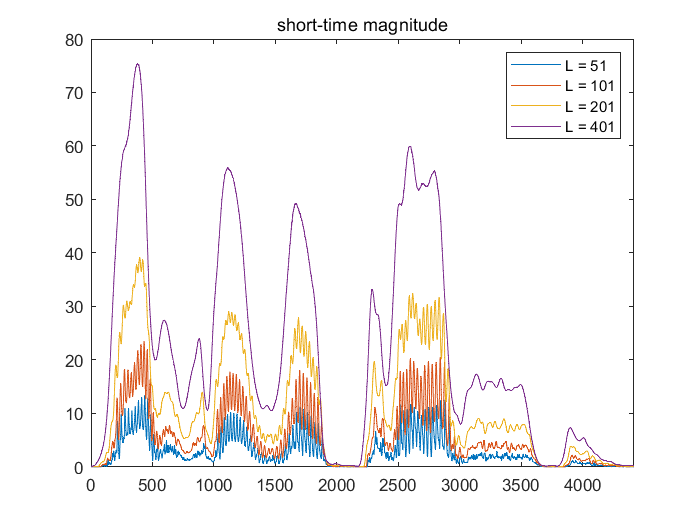

% short time magnitude
figure()
for j = 1:4
    stmagnitude = zeros(1, round((length(signal)-L(j))/R));
    window = hamming(L(j));
    for i = 1:length(stmagnitude)
        map_i = (i-1)*R+1;
        stmagnitude(i) = sum(abs(signal(map_i:map_i+L(j)-1)).*window);
    end
    plot(stmagnitude);title(sprintf('short-time magnitude'));xlim([0,length(stmagnitude)]);
    hold on
end
legend('L = 51','L = 101','L = 201','L = 401')
hold off

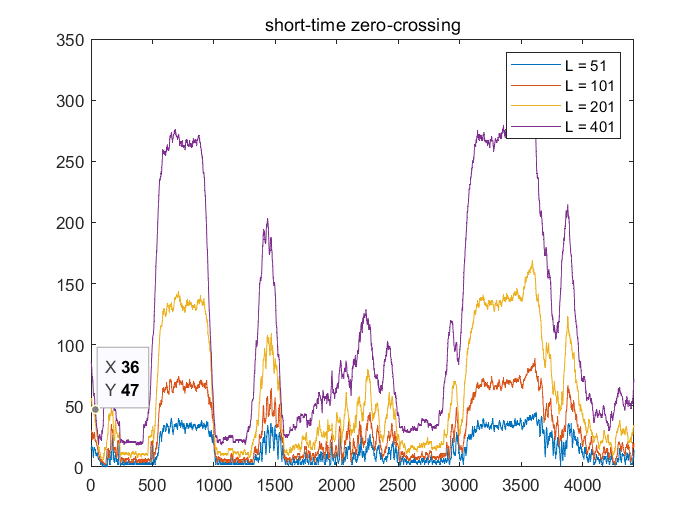

% short time zero crossing
figure()
for j = 1:4
    stzeroc = zeros(1, round((length(signal)-L(j))/R));
    Hzerocross = dsp.ZeroCrossingDetector;
    for i = 1:length(stzeroc)
        map_i = (i-1)*R+1;
        stzeroc(i) = step(Hzerocross,signal(map_i:map_i+L(j)-1));
    end
    plot(stzeroc);title(sprintf('short-time zero-crossing'));xlim([0,length(stzeroc)]);
    hold on
end
legend('L = 51','L = 101','L = 201','L = 401')
hold off